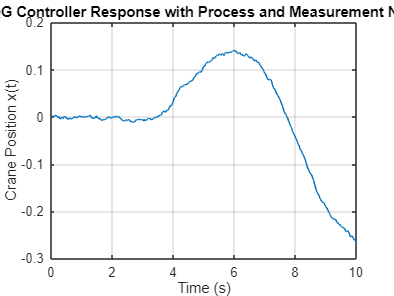


M = 1000;   % Mass of crane (kg)
m1 = 100;   % Mass of load 1 (kg)
m2 = 100;   % Mass of load 2 (kg)
l1 = 20;    % Length of cable 1 (m)
l2 = 10;    % Length of cable 2 (m)
g = 9.81;   % Gravitational acceleration (m/s^2)

% State-Space Matrices
A = [0 1 0 0 0 0;
     0 0 -m1*g/M 0 -m2*g/M 0;
     0 0 0 1 0 0;
     0 0 -g*(M+m1)/(l1*M) 0 -m2*g/(l1*M) 0;
     0 0 0 0 0 1;
     0 0 -m1*g/(l2*M) 0 -g*(M+m2)/(l2*M) 0];
 
B = [0; 1/M; 0; 1/(l1*M); 0; 1/(l2*M)];
C = [1 0 0 0 0 0]; % Output x(t) - chosen as the smallest vector
D = 0;

% LQR Design
Q = diag([100, 1, 100, 1, 100, 1]); 
R = 1;  
K = lqr(A, B, Q, R); %

% Kalman-Bucy Filter Design
V = eye(6);  % Process noise 
W = 1;       % Measurement noise 
L = lqe(A, V, C, V, W); % Kalman Gain

Bd = 0.1*eye(6);  
Vd = eye(6);      
Acl = [(A-B*K) (B*K); zeros(size(A)) (A-L*C)];
Bcl = [Bd; zeros(size(Bd))];
Ccl = [C zeros(size(C))];
Dcl = D;

sys_cl = ss(Acl, Bcl, Ccl, Dcl);
T = 0:0.01:10;  
r = ones(size(T)); 
w = randn(length(T), size(Bcl, 2)); 
[y, t, x] = lsim(sys_cl, w, T);

figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Crane Position x(t)');
title('LQG Controller Response with Process and Measurement Noise');
grid on;